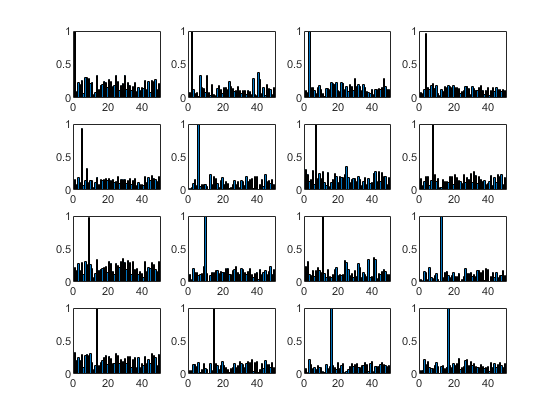

temp = 0;
for index = 1:17
    if index == 12
        continue
    end
    temp = temp + 1;
    eval(['load impuf50x50compareResult' num2str(index) '.mat']);
    subplot(4,4,temp)
    bar(Rmat)
end

load refIMG.mat
load testIMG.mat

Error using load
Unable to read file 'testIMG.mat'. No such file or directory.

figure,
[matchingRate, exactCorrectNum, iter_mat1] = algfixTesting(testIMG, refIMG);
load iter_mat.mat
subplot(2,1,1)
bar(iter_mat)
title('similiar dendrite 1 (iteration times vs matchingRate)')
subplot(2,1,2)
bar(iter_mat1)
title('similiar dendrite 2 (iteration times vs matchingRate)')
load('refIMG.mat')
rot = imrotate(refIMG,180);
figure,
algfixTesting(rot, refIMG)